clear; clc; close all;

addpath('../scripts')
warning('off', 'all');

% Read the test data.
testDataFolderName = '20241016';
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);

% Instantiate a RobotSimulator class.
dt = .1;
steps = 10;
robotSimulator = RobotSimulator(steps, dt);
robotSimulator.simulinkMdl = 'main4_armpi_fpv.slx'; % Use the new version of the simulation model that considers the motor dynamics.

dataLoader.pathLoggedTestData = ['../dataset/testDatasets/' testDataFolderName '/real_testing_dataset.mat'];
dataLoader.pathTestDataset = ['../dataset/testDatasets/' testDataFolderName '/'];
dataLoader.pathOriginalTestData = ['../dataset/testDatasetsOriginal/' testDataFolderName '/'];
dataLoader.nTrajPerLabelTestDataset = 10;
dataLoader.labelList = {'Healthy', ...
    'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
    'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'};
    
[X_test, y_test] = dataLoader.loadTestingData();

Loaded data from ../dataset/testDatasets/20241016/real_testing_dataset.mat


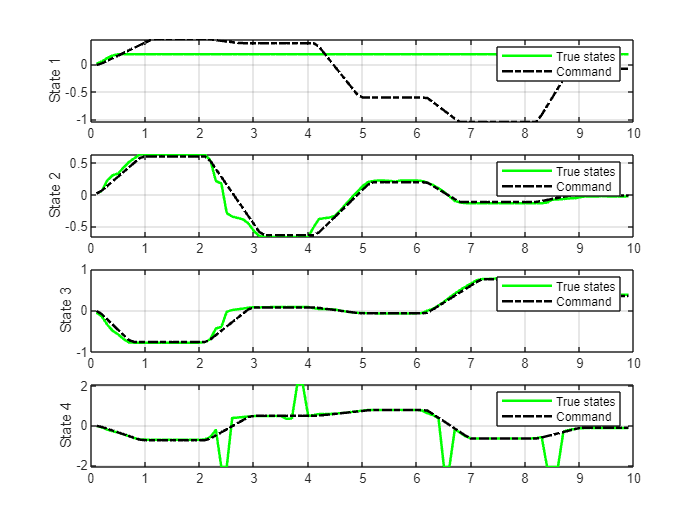

% Get one test data.
idx = 21;
dataset = X_test{idx};

% Define the dimensions.
state_dim = 8; % Number of state variables.
% N = numel(1:steps:size(dataset, 1)-steps);
N = numel(1:steps:size(dataset, 1)-steps);

% Extract the variables.
U = zeros(N, state_dim);
U(:, 1:4) = dataset{1:steps:end-steps, 2:5}; % Inputs to 1-4 motors.
U(:, 5:end) = 0; % If we have stuck faults.

Z = dataset{steps+1:steps:end, 10:12}; % Observations
time = dataset{1:steps:end-steps, 1}; % Times

% Prepare the observer.
obs_dim = size(Z, 2); % Number of observations

% Get the true response.
matfile_path = dataset.matFilePath{1};
matfile_path = strrep(matfile_path, 'dataset_', 'hidden_dataset_');
hidden_data_set = load(matfile_path);

x_true = zeros(state_dim, N);
for i = 1:4
    x_true(i, :) = hidden_data_set.motorRespsRadius{i}.Data(steps+1:steps:end);
end

% Plot results
t = (1:N) * dt;
figure;
for i = 1:4
    subplot(4, 1, i);
    plot(t, x_true(i, :), 'g-', 'LineWidth', 1.5); hold on;
    plot(t, U(:, i), 'k-.', 'LineWidth', 1.5); hold on;
    ylabel(['State ', num2str(i)]);
    legend('True states', 'Command');
    grid on;
end

% State variables initialization
% x_true = zeros(state_dim, 1); % True initial state
x_est = zeros(state_dim, 1); % Estimated initial state
P = eye(state_dim); % Initial state covariance

% Input and noise parameters
Q = 0.1 * eye(state_dim); % Process noise covariance
for i = 5:8
    if i == 5
        Q(i, i) = .1;
    end
    Q(i, i) = .001;
end

R = 0.01 * eye(obs_dim); % Measurement noise covariance
delta = 1e-5; % Perturbation size for numerical Jacobian

% Define simulation model placeholders
f_sim = @(x, u) simulation_state_transition(x, u, robotSimulator, steps); % Placeholder for simulation state transition
h_sim = @(x) simulation_observation(x, robotSimulator); % Placeholder for simulation observation

% Numerical Jacobian approximation
numerical_jacobian = @(f, x, u, delta) compute_jacobian(f, x, u, delta);

% Simulation and estimation
% x_history = zeros(state_dim, N);
z_est_history = zeros(obs_dim, N);
x_est_history = zeros(state_dim, N);

threshold = 0.01;
window = 3;
for k = 1:N
    fprintf('%d / %d th iteration:\n', k, N);

    % Get the observed value at the current step.
    z = transpose(Z(k, :));
    u = transpose(U(k, :));
    
    % Prediction step
    x_pred = f_sim(x_est, u);
    F = numerical_jacobian(f_sim, x_est, u, delta);
    P = F * P * F' + Q;
    
    % Update step
    H = numerical_jacobian(h_sim, x_pred, [], delta);
    K = P * H' / (H * P * H' + R);
    z_est = h_sim(x_pred);

    % Calculate the estiamtion residual
    res = (z - z_est);    

    x_est = x_pred + K*res;
    for i = 5:8
        if x_est(i) < 0.5
            x_est(i) = 0;
        else
            x_est(i) = 1;
        end
    end

    if sqrt(sum(res.^2)) > threshold
        idx = 3;
        x_est(idx) = mean(x_est_history(idx, k-window:k-1));
        x_est(idx+4) = 1;
    % else
    %     x_est(5) = 0;
    end

    P = (eye(state_dim) - K * H) * P;
    
    % Store results
    z_est_history(:, k) = z_est;
    x_est_history(:, k) = x_est;

    fprintf('uk:');
    u'
    fprintf('xk:');
    x_true(:, k)'
    fprintf('residual: %.3f\n', sqrt(sum(res.^2)));    

    fprintf('x_pred:\n');
    x_pred'
    fprintf('x_est:\n');
    x_est'
end

1 / 99 th iteration:


uk:

ans =    -0.0126    0.0168   -0.0084   -0.0126         0         0         0         0


xk:

ans =     0.0083    0.0168   -0.0501   -0.0209         0         0         0         0


residual: 0.007


x_pred:


ans =    -0.0134    0.0178   -0.0089   -0.0135         0         0         0         0


x_est:


ans =    -0.0134    0.0088   -0.0143   -0.0154         0         0         0         0


2 / 99 th iteration:


uk:

ans =     0.0192    0.0655   -0.0914   -0.0735         0         0         0         0


xk:

ans =     0.0544    0.0628   -0.1424   -0.0963         0         0         0         0


residual: 0.009


x_pred:


ans =     0.0213    0.0692   -0.0964   -0.0777         0         0         0         0


x_est:


ans =     0.0213    0.0568   -0.1040   -0.0803         0         0         0         0


3 / 99 th iteration:


uk:

ans =     0.0669    0.1388   -0.2164   -0.1651         0         0         0         0


xk:

ans =     0.1173    0.2261   -0.3434   -0.2052         0         0         0         0


residual: 0.003


x_pred:


ans =     0.0699    0.1441   -0.2237   -0.1713         0         0         0         0


x_est:


ans =     0.0699    0.1456   -0.2233   -0.1713         0         0         0         0


4 / 99 th iteration:


uk:

ans =     0.1147    0.2121   -0.3414   -0.2567         0         0         0         0


xk:

ans =     0.1634    0.3058   -0.4901   -0.2890         0         0         0         0


residual: 0.005


x_pred:


ans =     0.1176    0.2164   -0.3490   -0.2629         0         0         0         0


x_est:


ans =     0.1176    0.2168   -0.3502   -0.2637         0         0         0         0


5 / 99 th iteration:


uk:

ans =     0.1624    0.2854   -0.4663   -0.3484         0         0         0         0


xk:

ans =     0.1860    0.3351   -0.5781   -0.3561         0         0         0         0


residual: 0.006


x_pred:


ans =     0.1653    0.2898   -0.4739   -0.3545         0         0         0         0


x_est:


ans =     0.1654    0.2848   -0.4786   -0.3565         0         0         0         0


6 / 99 th iteration:


uk:

ans =     0.2102    0.3587   -0.5913   -0.4400         0         0         0         0


xk:

ans =     0.1860    0.4272   -0.6869   -0.4482         0         0         0         0


residual: 0.005


x_pred:


ans =     0.2131    0.3635   -0.5986   -0.4461         0         0         0         0


x_est:


ans =     0.2130    0.3670   -0.5983   -0.4467         0         0         0         0


7 / 99 th iteration:


uk:

ans =     0.2579    0.4320   -0.7163   -0.5316         0         0         0         0


xk:

ans =     0.1860    0.5152   -0.7707   -0.5403         0         0         0         0


residual: 0.011


x_pred:


ans =     0.2608    0.4362   -0.7239   -0.5378         0         0         0         0


x_est:


ans =     0.2607    0.4510   -0.4757   -0.5363         0         0    1.0000         0


8 / 99 th iteration:


uk:

ans =     0.3057    0.5053   -0.7582   -0.6233         0         0         0         0


xk:

ans =     0.1860    0.5738   -0.7749   -0.6367         0         0         0         0


residual: 0.029


x_pred:


ans =     0.3086    0.5088   -0.4757   -0.6296         0         0    1.0000         0


x_est:


ans =     0.3087    0.4812   -0.5175   -0.6394         0         0    1.0000         0


9 / 99 th iteration:


uk:

ans =     0.3534    0.5786   -0.7582   -0.7149         0         0         0         0


xk:

ans =     0.1860    0.6367   -0.7749   -0.7037         0         0         0         0


residual: 0.025


x_pred:


ans =     0.3563    0.5849   -0.5175   -0.7204         0         0    1.0000         0


x_est:


ans =     0.3559    0.5619   -0.5305   -0.7281         0         0    1.0000         0


10 / 99 th iteration:


Error using RobotSimulator/simulateMotorResponses
Program interruption has been detected.

Error in testEKFRealDataFault>simulation_state_transition (line 241)
    motorRespsRadius = robotSimulator.simulateMotorResponses(motorCmds);

Error in 

% Plot results
t = (1:N) * dt;
figure;
for i = 1:state_dim
    subplot(state_dim, 1, i);
    plot(t, x_true(i, :), 'g-', 'LineWidth', 1.5); hold on;
    plot(t, x_est_history(i, :), 'r--', 'LineWidth', 1.5); hold on;
    plot(t, U(:, i), 'k-.', 'LineWidth', 1.5); hold on;
    ylabel(['State ', num2str(i)]);
    legend('True states', 'Estimated states', 'Command');
    grid on;
end
xlabel('Time (s)');
sgtitle('EKF with Simulation-Based State Space Model');

figure;
for i = 1:obs_dim
    subplot(obs_dim, 1, i);
    plot(t, Z(:, i), 'g-', 'LineWidth', 1.5); hold on;
    plot(t, z_est_history(i, :), 'r--', 'LineWidth', 1.5); hold on;
    ylabel(['State ', num2str(i)]);
    legend('True observation', 'Estimated observation');
    grid on;
end
xlabel('Time (s)');
sgtitle('EKF with Simulation-Based State Space Model');


% Helper function

function J = compute_jacobian(f, x, u, delta)
    % Compute the Jacobian numerically using finite differences
    n = length(x); % Dimension of the state vector
    % Check if the function takes two arguments (x, u) or just x
    if nargin(f) == 2
        % Function takes both state and input
        m = length(f(x, u)); % Dimension of the function output
        J = zeros(m, n); % Initialize Jacobian matrix
        old_value = f(x, u);
        for i = 1:n
            dx = zeros(size(x));
            if i >= 5
                delta = 1;
            end
            dx(i) = delta; % Perturb the i-th state
            J(:, i) = (f(x + dx, u) - old_value) / delta;
        end
    else
        % Function takes only state
        m = length(f(x)); % Dimension of the function output
        J = zeros(m, n); % Initialize Jacobian matrix
        old_value = f(x);
        for i = 1:n
            dx = zeros(size(x));
            if i >= 5
                delta = 1;
            end
            dx(i) = delta; % Perturb the i-th state
            J(:, i) = (f(x + dx) - old_value) / delta;
        end
    end
end


function x_next = simulation_state_transition(x, u, robotSimulator, steps)
    % Set the control command.
    n_inputs = 5;
    motorCmds = cell(1, n_inputs);

    flags = x(5:end);
    flags(flags<0.5) = 0;
    flags(flags>=0.5) = 1;
    for i = 1:n_inputs-1
        signal = (1-flags(i))*u(i)*ones(steps, 1) + flags(i)*x(i)*ones(steps, 1);
        motorCmds{i} = timeseries(signal, robotSimulator.simulationTimeStamps);
    end
    motorCmds{n_inputs} = timeseries(zeros(steps, 1), robotSimulator.simulationTimeStamps);
    motorCmds = robotSimulator.cmdsRadius2Unit(motorCmds);

    % Set the initial values.
    robotSimulator.joint1Init = x(1);
    robotSimulator.joint2Init = x(2);
    robotSimulator.joint3Init = x(3);
    robotSimulator.joint4Init = x(4);
    robotSimulator.setModelParameters(); % Update the parameters in the simulink model

    % Run a simulation and show the results.
    robotSimulator.motorCommands = motorCmds;
    
    motorRespsRadius = robotSimulator.simulateMotorResponses(motorCmds);

    % Example simulation for state transition
    x_next = [
        motorRespsRadius{1}.Data(end);
        motorRespsRadius{2}.Data(end);
        motorRespsRadius{3}.Data(end);
        motorRespsRadius{4}.Data(end);
        flags(1);
        flags(2);
        flags(3);
        flags(4);
    ];
end

function z = simulation_observation(x, robotSimulator)
    
    n_cmds = 4;
    motorRespsRadius = cell(1, n_cmds);
    for i = 1:numel(x)
        motorRespsRadius{i} = timeseries(x(i), 0);
    end

    trajResponses = robotSimulator.virtualSensor(motorRespsRadius);

    % Example simulation for observation
    z = trajResponses';
end